## demos for ch03

clear; close all;
d = 1;
n = 200;
[x,t] = linRnd(d,n);

## Empirical Bayesian linear regression via Mackay fix point iteration method

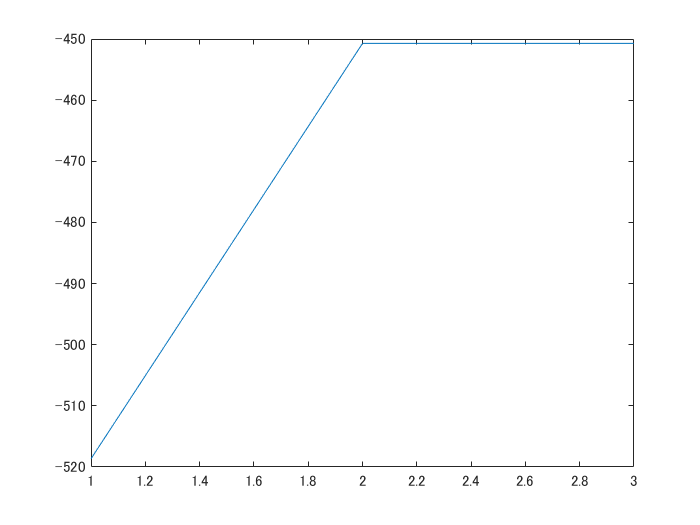

[model,llh] = linRegFp(x,t);
plot(llh);

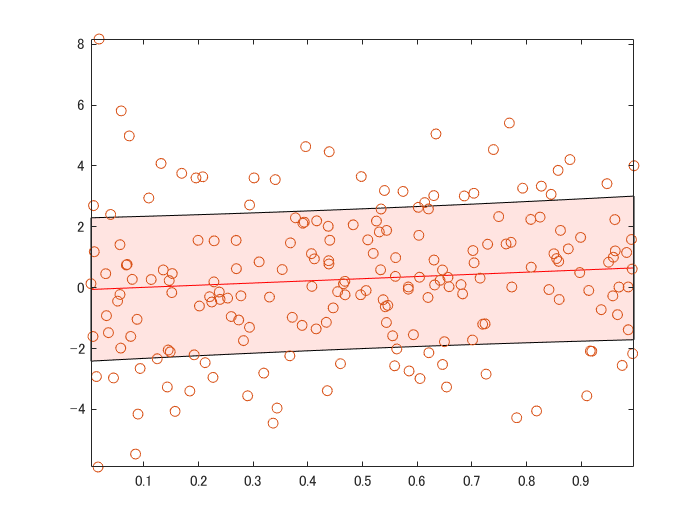

[y,sigma] = linRegPred(model,x,t);
figure
plotCurveBar(x,y,sigma);
hold on;
plot(x,t,'o');
hold off;